# Test met functies


toy_samples = 150;
nb_inputs = 2;
nb_outputs = 3;

sampling_points = rand(nb_inputs, toy_samples);
%sampling_points(1,:) = linspace(-2,2,250);
%sampling_points(2,:) = linspace(-2,2,250);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [~, Jac(1,:,i)] = dlfeval(@f1, point);
    [~, Jac(2,:,i)] = dlfeval(@f2, point);
    [~, Jac(3,:,i)] = dlfeval(@f3, point);
end

## Test met neuraal netwerk [ 2 2 3 4 2 2]


toy_samples = 100;
nb_inputs = 2;
nb_outputs = 2;

sampling_points = randn(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [~, Jac(:,:,i)] = dlfeval(@all_layers, point);
end

## Test met eenvoudige functie

toy_samples = 10;
nb_inputs = 2;
nb_outputs = 2;

sampling_points = randn(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [~, Jac(:,:,i)] = dlfeval(@unique, point);
end

## Algoritme oproep

warning("off")

bf1 = {@theta1, @theta2, @theta3, @theta4, @theta5};%, @theta7, @theta8, @theta9, @theta10};
bf1d = {@theta1d, @theta2d, @theta3d, @theta4d, @theta5d};
bf2d = {@theta1d, @theta2d, @theta3d, @theta4d, @theta5d};%, @theta6, @theta7, @theta8, @theta9, @theta10};

%bf1 = {@theta1, @theta2, @theta3};%, @theta4};
%bf2 = {@theta1, @theta2, @theta3};%, @theta4};


r1 = 5;
r2 = 8;

tic
[We, D2e, Vte, D1e, Zte, cD1e, cD2e] = PARATUCK2_CTD(Jac, bf1, bf1d, bf2d, r1, r2, sampling_points);

i = 1

Jerror = 0.9485

i = 2

Jerror = 0.7533

i = 3

Jerror = 0.6748

i = 4

Jerror = 0.6376

i = 5

Jerror = 0.6299

i = 6

Jerror = 0.6284

i = 7

Jerror = 0.6282

i = 8

Jerror = 0.6279

i = 9

Jerror = 0.6280

i = 10

Jerror = 0.6278

i = 11

Jerror = 0.6279

i = 12

Jerror = 0.6280

i = 13

Jerror = 0.6283

i = 14

Jerror = 0.6282

i = 15

Jerror = 0.6278

i = 16

Jerror = 0.6272

i = 17

Jerror = 0.6268

i = 18

Jerror = 0.6263

i = 19

Jerror = 0.6260

i = 20

Jerror = 0.6256

i = 21

Jerror = 0.6255

i = 22

Jerror = 0.6254

i = 23

Jerror = 0.6255

i = 24

Jerror = 0.6257

i = 25

Jerror = 0.6260

i = 26

Jerror = 0.6263

i = 27

Jerror = 0.6265

i = 28

Jerror = 0.6265

i = 29

Jerror = 0.6267

i = 30

Jerror = 0.6268

i = 31

Jerror = 0.6266

i = 32

Jerror = 0.6258

i = 33

Jerror = 0.6251

i = 34

Jerror = 0.6250

i = 35

Jerror = 0.6251

i = 36

Jerror = 0.6249

i = 37

Jerror = 0.6247

i = 38

Jerror = 0.6245

i = 39

Jerror = 0.6244

i = 40

Jerror = 0.6246

i = 41

Jerror = 0.6249

i = 42

Jerror = 0.6252

i = 43

Jerror = 0.6254

i = 44

Jerror = 0.6255

i = 45

Jerror = 0.6256

i = 46

Jerror = 0.6255

i = 47

Jerror = 0.6255

i = 48

Jerror = 0.6255

i = 49

Jerror = 0.6255

i = 50

Jerror = 0.6256

minError = 0.6244

toc

Elapsed time is 43.123377 seconds.


## Compute constant terms

biasVec = zeros(toy_samples * nb_outputs,1);
Wvec = zeros(toy_samples * size(We,1), size(We,2));
for i=1:toy_samples
    biasVec((i-1) * nb_outputs + 1: i * nb_outputs) = ...
        F(:,i) - fbar(sampling_points(:,i), We, Vte, Zte, cD1e, cD2e, r1, r2);

    Wvec((i-1) * size(We,1) + 1: i * size(We,1), :) = We;
end

cBias = Wvec \ biasVec;

cD2e_2 = zeros(size(cD2e,1) + r2,1);
d = size(bf2d,2) + 1;
biasIdx = 1;
for i=1:r2
    cD2e_2((i-1) * d + 1) = cBias(biasIdx);
    biasIdx = biasIdx + 1;

    cD2e_2((i-1)* d + 2: i * d) = cD2e((i-1) * (d-1) + 1: i * (d-1));
end

%size(cD2e_2)
cD2e = cD2e_2;

## Vergelijking met functies

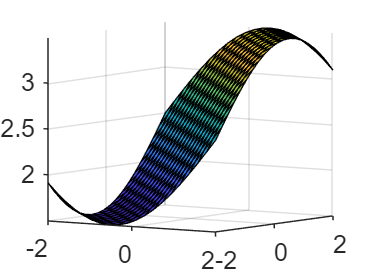

x = linspace(-2,2,20);
y = x';
z = zeros(20);
zb = zeros(20,20,nb_outputs);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f1, point);
        zb(i,j,:) = fbar([x(i); y(j)], We, Vte, Zte, cD1e, cD2e, r1, r2);
    end
end

% Origineel
surf(x,y,z)
set(gca,'FontSize',15)
view([35.05 6.20])

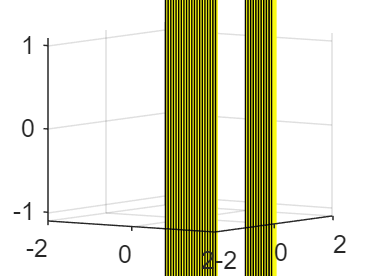

% Benadering
surf(x,y,zb(:,:,1))
set(gca,'FontSize',15)
view([35.05 6.20])
zlim([-1.1 1.1])

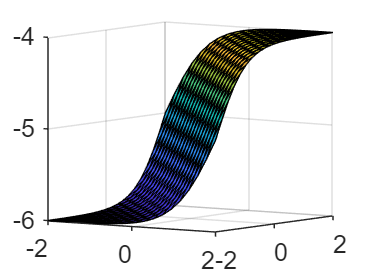



z = zeros(20);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f2, point);
    end
end

% Origineel
surf(x,y,z)
set(gca,'FontSize',15)
view([35.05 6.20])

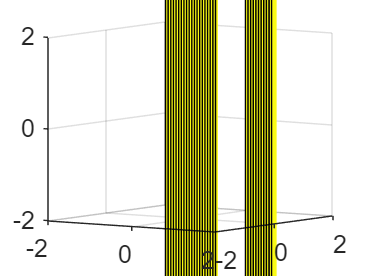

% Benadering
surf(x,y,zb(:,:,2))
set(gca,'FontSize',15)
view([35.05 6.20])
zlim([-2 2])

## Vergelijking met netwerk

u = dlarray([0.48 0.44]);
[result, ~] = dlfeval(@all_layers, u);
result

result =    -0.0252
    0.1474



apprResult = fbar(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult

apprResult =    -0.0116
    0.0680


## Vergelijking met eenvoudige functie

u = dlarray([0.48 0.44]);
[result, ~] = dlfeval(@unique, u);
result

result =   2×1 dlarray

  -63.0624
  -35.7648



apprResult = fbarEasy(u', We, Vte, Zte, cD1e, cD2e, r1, r2);
apprResult

apprResult =    17.8633
   36.2349


## Vergelijking functies (paper)

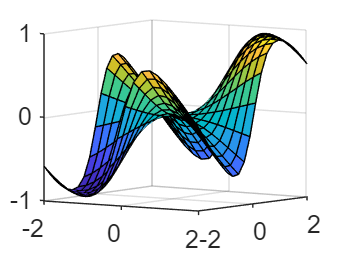

x = linspace(-2,2,20);
y = x';
z = zeros(20);
zb = zeros(20,20,nb_outputs);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f11, point);
        zb(i,j,:) = fbar([x(i); y(j)], We, Vte, Zte, cD1e, cD2e, r1, r2);
    end
end

% Origineel
surf(x,y,z)
set(gca,'FontSize',15)
view([35.05 6.20])

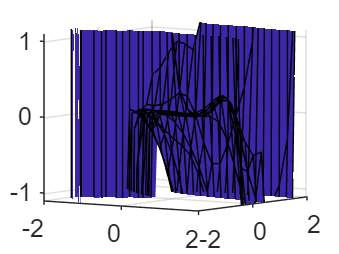

% Benadering
surf(x,y,zb(:,:,1))
set(gca,'FontSize',15)
view([35.05 6.20])
zlim([-1.1 1.1])

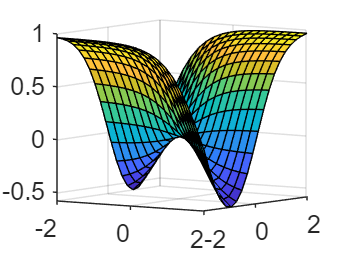



z = zeros(20);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f22, point);
    end
end

% Origineel
surf(x,y,z)
set(gca,'FontSize',15)
view([35.05 6.20])

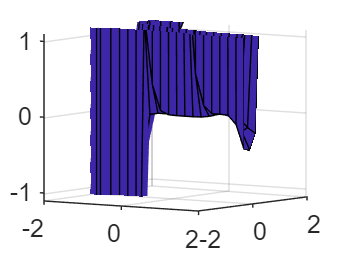

% Benadering
surf(x,y,zb(:,:,2))
set(gca,'FontSize',15)
view([35.05 6.20])
zlim([-1.1 1.1])

## Resultaten opslaan

save("SavedVariables/PARATUCK2/Structured/PT2_toy_functions_3_3_S400");

load("SavedVariables/PARATUCK2/Structured/CTD/PT2_toy_functions_2_3_S150_1.mat");

function [f,grad] = f1(x)
    f = 2.5 + sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end

function [f,grad] = f11(x)
    f = sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end

function [f,grad] = f2(x)
    f = -5 + tanh(sum(x));
    grad = dlgradient(f,x);
end

function [f,grad] = f22(x)
    f = tanh(sum(x)) * tanh(x(1));
    grad = dlgradient(f,x);
end

function [f,grad] = f3(x)
    f = cos(sum(x)) - 1;
    grad = dlgradient(f,x);
end

function[f,grad] = all_layers(x)
    W0 = [0.2, 0.4; 0.5, 0.1];
    W1 = [0.02, 0.3; 0.1, 0.4; 0.2, 0.6];
    W2 = [0.3, 0.3, 0.6; 0.1, 0.4, 0.5; 0.2, 0.5, 0.6; 0, 0.3, 0.4];
    W3 = [0.2, 0.4 0.3 0.3; 0.5, 0.1 0.5 0.2];
    W4 = [-0.7 0.3; 0.5, 1.3];

    interm1 = arrayfun(@relu, W0*x');
    interm2 = arrayfun(@relu, W1 * interm1);
    interm3 = arrayfun(@relu, W2 * interm2);
    interm4 = arrayfun(@relu, W3 * interm3);


    f1 = W4(1,:)*interm4;
    f2 = W4(2,:)*interm4;

    f = zeros(2,1);
    f(1) = f1;
    f(2) = f2;
    %f(3) = f3;
    %f(4) = f4;

    grad1 = dlgradient(f1,x);
    grad2 = dlgradient(f2,x);
    %grad3 = dlgradient(f3,x);
    %grad4 = dlgradient(f4,x);

    grad = zeros(2,2);
    grad(1,:) = grad1;
    grad(2,:) = grad2;
    %grad(3,:) = grad3;
    %grad(4,:) = grad4;
end


function [f] = fbar(input, W, Vt, Zt, cD1, cD2, r1, r2)
    P1 = zeros(r1,1);
    x = Zt * input;
    for i=1:r1
        P1(i,1) = cD1((5* (i - 1)) + 1) * x(i) + ...
                 cD1((5* (i - 1)) + 2) * x(i)^2 + ...
                 cD1((5* (i - 1)) + 3) * x(i)^3 + ...
                 cD1((5* (i - 1)) + 4) * x(i)^4 + ...
                 cD1((5* (i - 1)) + 5) * x(i)^5;% + ...
                 %cD1((10* (i - 1)) + 6) * x(i)^6 + ...
                 %cD1((10* (i - 1)) + 7) * x(i)^7 + ...
                 %cD1((10* (i - 1)) + 8) * x(i)^8 + ...
                 %cD1((10* (i - 1)) + 9) * x(i)^9 + ...
                 %cD1((10* (i - 1)) + 10) * x(i)^10;
    end

    P2 = zeros(r2,1);
    x = Vt * P1;
    for i=1:r2
        P2(i,1) = cD2((5* (i - 1)) + 1) * x(i) + ...
                 cD2((5* (i - 1)) + 2) * x(i)^2 + ...
                 cD2((5* (i - 1)) + 3) * x(i)^3 + ...
                 cD2((5* (i - 1)) + 4) * x(i)^4 + ...
                 cD2((5* (i - 1)) + 5) * x(i)^5; % + ...
                 %cD2((10* (i - 1)) + 6) * x(i)^6 + ...
                 %cD2((10* (i - 1)) + 7) * x(i)^7 + ...
                 %cD2((10* (i - 1)) + 8) * x(i)^8 + ...
                 %cD2((10* (i - 1)) + 9) * x(i)^9 + ...
                 %cD2((10* (i - 1)) + 10) * x(i)^10;
    end

    f = W * P2;
end

function [f] = fbarEasy(input, W, Vt, Zt, cD1, cD2, r1, r2)
    P1 = zeros(r1,1);
    x = Zt * input;
    for i=1:r1
        P1(i,1) = cD1((3* (i - 1)) + 1) * x(i) + ...
                 cD1((3* (i - 1)) + 2) * x(i)^2 + ...
                 cD1((3* (i - 1)) + 3) * x(i)^3;% + ...
                 %cD1((4* (i - 1)) + 4) * x(i)^4;
    end

    P2 = zeros(r2,1);
    x = Vt * P1;
    for i=1:r2
        P2(i,1) = cD2((3* (i - 1)) + 1) * x(i) + ...
                 cD2((3* (i - 1)) + 2) * x(i)^2 + ...
                 cD2((3* (i - 1)) + 3) * x(i)^3;% + ...
                 %cD2((4* (i - 1)) + 4) * x(i)^4;
    end

    f = W * P2;
end


function [f] = theta1(x)
    f = x;
end

function [f] = theta1d(x)
    f = 1;
end

function [f] = theta2(x)
    f = x^2;
end

function [f] = theta2d(x)
    f = 2*x;
end

function [f] = theta3(x)
    f = x^3;
end

function [f] = theta3d(x)
    f = 3*x^2;
end

function [f] = theta4(x)
    f = x^4;
end

function [f] = theta4d(x)
    f = 4*x^3;
end

function [f] = theta5(x)
    f = x^5;
end

function [f] = theta5d(x)
    f = 5*x^4;
end

function [f] = theta6(x)
    f = x^6;
end

function [f] = theta6d(x)
    f = 6*x^5;
end

function [f,grad] = theta7(x)
    f = x^7;
    grad = dlgradient(f,x);
end

function [f,grad] = theta8(x)
    f = x^8;
    grad = dlgradient(f,x);
end

function [f,grad] = theta9(x)
    f = x^9;
    grad = dlgradient(f,x);
end

function [f,grad] = theta10(x)
    f = x^10;
    grad = dlgradient(f,x);
end

function [f,grad] = unique(x)
    Ut = [-2 -2; -3 1];
    Vt = [1 2; -3 -1];
    W = [1 2; 2 1];

    univ1 = Ut * x';
    result1 = h(univ1);

    univ2 = Vt * result1;

    result2 = g(univ2);

    f = W * result2;

    f1 = f(1);
    f2 = f(2);

    grad1 = dlgradient(f1,x);
    grad2 = dlgradient(f2,x);

       
    grad = zeros(2,2);
    grad(1,:) = grad1;
    grad(2,:) = grad2;

end

function [res] = h(x)
    res1 = 2*x(1);
    res2 = x(2)^2;
    res = [res1; res2];
end

function [res] = g(x)
    res1 = -x(1)^2;
    res2 = -3*x(2);
    res = [res1; res2];
end